# Play around with LASSO regression on Octane dataset

**This Live Script is designed to allow you to vary the value of the regularization parameter ("lambda") used in LASSO regression.**

Observe its effect on:

- the number of features (wavelengths) that have non-zero regression coefficients

- the value of RMSECV

%% Load spectra and octane values, split into training and test holdout datasets
clear;
close all;
load spectra;
CV = cvpartition(height(NIR),"HoldOut",0.3);

NIR_train = NIR(CV.training,:);
NIR_train_c = normalize(NIR_train,"center");
NIR_test = NIR(CV.test,:) - mean(NIR_train);
octane_train = octane(CV.training);
octane_test = octane(CV.test);
wavelength = 900:2:1700;

## Vary value of lambda and fit using lasso()

Use slider to vary the value of the logarithm of the lambda regularization parameter ("logLambda"). The log is used to make it easier to span a wide range of values.

logLambda =-1.3;
[B, FitInfo] = lasso(NIR_train_c,octane_train,'Lambda',10^logLambda);
b = B;
b0 = FitInfo.Intercept;

## Plot regression coefficients overlayed with average NIR spectrum

Observe how many and which features (i.e. wavelengths) have non-zero regression coefficients as you vary the value of logLambda (above). How does the number of features used change as logLambda is decreased?

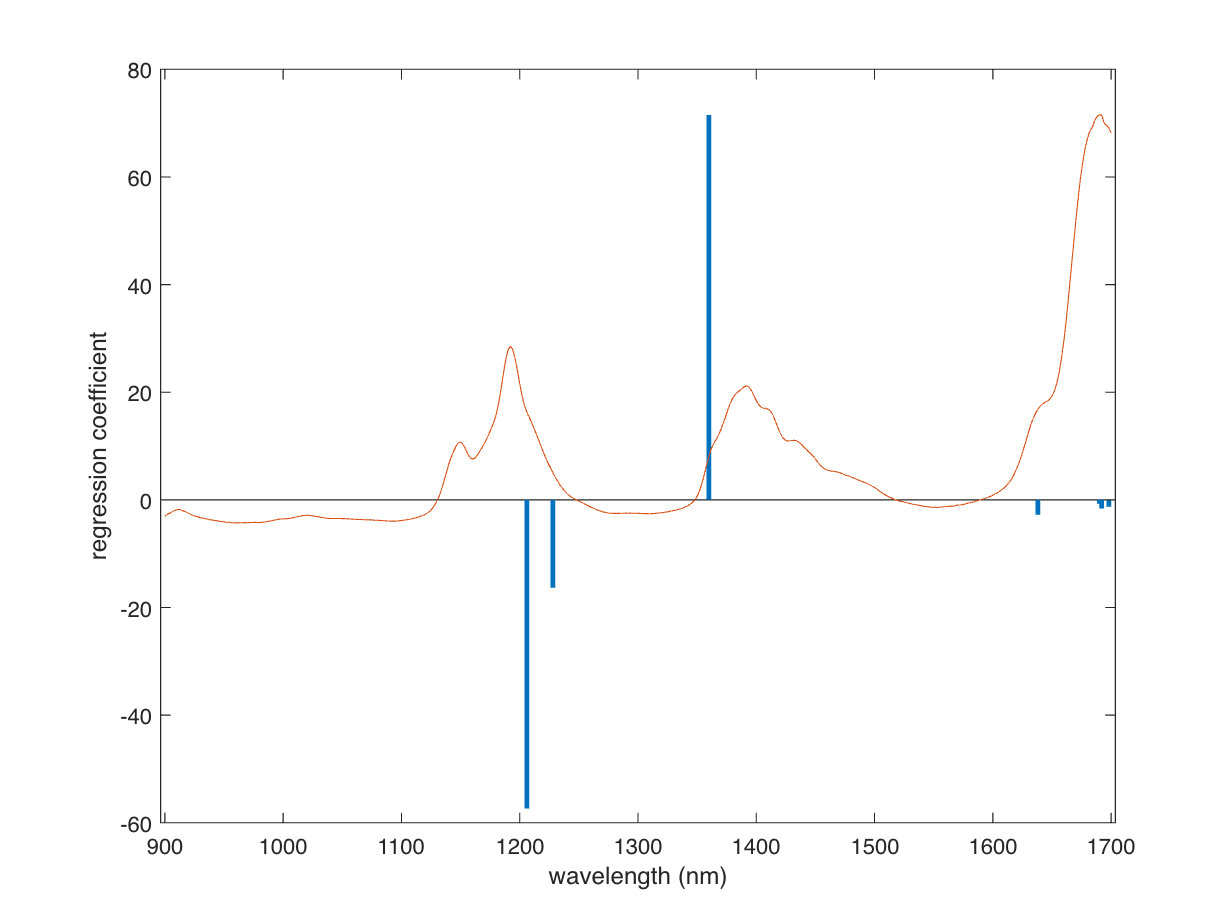

% plot regression coefficients overlayed with average NIR spectrum
figure
bar(wavelength,b,2);
hold on
plot(wavelength,mean(NIR_train)*max(b)/max(mean(NIR_train)));
xlabel("wavelength (nm)");
ylabel("regression coefficient");

disp("Number of wavelengths with non-zero coefficients: " + length(find(b)))

Number of wavelengths with non-zero coefficients: 7


## Predict octane for test dataset, plot, calculate RMSECV

Look at how well the LASSO model does on the held out test dataset. What trend do you notice with RMSECV and the number of features used?


% predicted octane values
octane_pred = b0 + NIR_test*b;
RMSECV = sqrt(sumsqr(octane_pred-octane_test)/length(octane_pred))

RMSECV = 0.2755

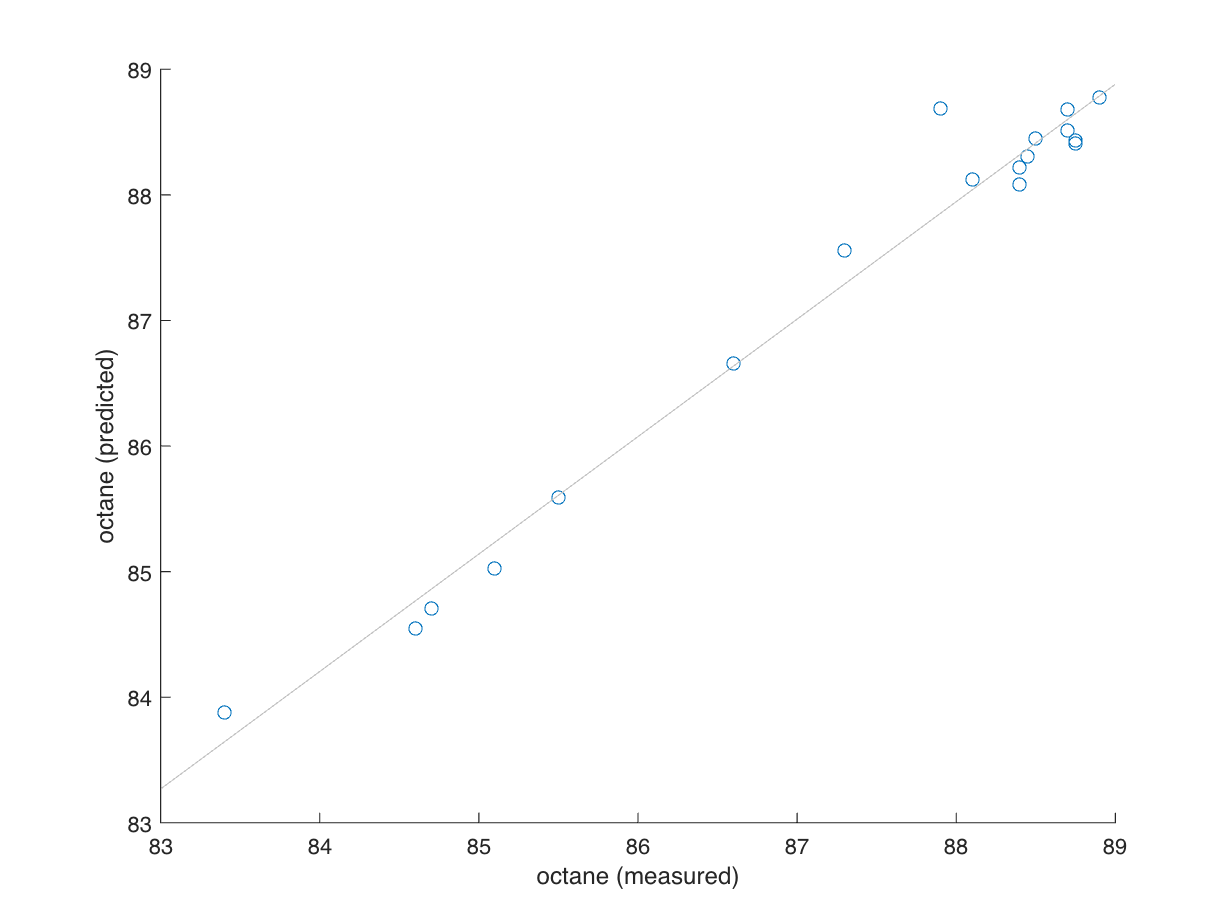

figure;
scatter(octane_test,octane_pred);
hold on
lsline
xlabel("octane (measured)");
ylabel("octane (predicted)");